## Load MNIST dataset

trainSamples = 1000;
testSamples = 100;
[trainImgs, trainLbls] = loadDataset(trainSamples, 'train');
[testImgs, testLbls] = loadDataset(testSamples, 'test');

## Initialize parameters and reserve memory

% Depth of the synaptic filters
dpth = 10;
% Number of neurons
n = 10;
% Number of synapses
nSyn = 28*28;
% Synaptic currents
ISyn = zeros(nSyn, n);
% Synaptic kernel
j = 1:dpth;
dt = 0.5; % [ms]
tau = 1; % [ms]
alpha = j*dt/tau .* exp(-j*dt/tau);
% Weights
w = zeros(nSyn, n);
w(:, :) = 0.1;
% Weights reservoir
wResevs = 500 * ones(n);
% Number of positive weights
wGrtZero = nSyn * ones(n);
% Input spikes
spksIn = zeros(nSyn, n);
% Input firing rates
nuIn = zeros(nSyn, n);
% Output firing rates
nuOut = zeros(n);
% Input spike trains
spkTrnsIn = zeros(nSyn, dpth, n);
% Output spikes
spksOut = zeros(n, 1);
% Membrane potential
v = zeros(n, 1);
v(1:n) = -70;
% Recovery variable
u = zeros(n, 1);
u(1:n) = -14;

## Train the network

ordImgs = orderImgs(trainImgs, trainLbls);
% Number of images should be a multiple of the number of labels
maxImg = floor(size(ordImgs, 3)/10)*10;
% How many times the same pictures are sent to the neurons
times = 8;
% Each neuron receives a different img, therfore
% the index must be incremented by 10
for i = 1:10:maxImg
    for t = 1:times
        for j = 1:10      
          % Generate the input spikes from the picture
          spksIn(:, j) = generateSpikes(ordImgs(:, :, i + j-1));
          % Update the spike train using the newly generated input spikes
          spkTrnsIn(:, :, j) = updtSpkTrn(spksIn(:, j), spkTrnsIn(:, :, j));
          % Stimulate the neuron with the spike trains
          [spksOut(j), v(j), u(j)] = simulateNrn(spkTrnsIn(:, :, j), w(:, j), v(j), u(j), alpha);
          % Update the weights
          [w(:, j), nuIn(:, j), nuOut(j), wResevs(j), wGrtZero(j)] = updtWs(nuIn(:, j), nuOut(j), spksIn(:, j), spksOut(j), w(:, j), wResevs(j), wGrtZero(j));
        end
    end  
end

## Plot the maps of the weights

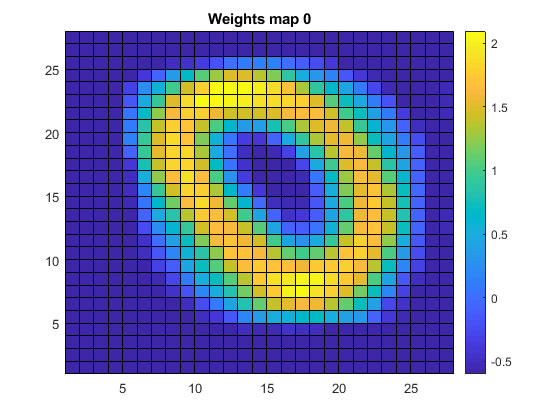

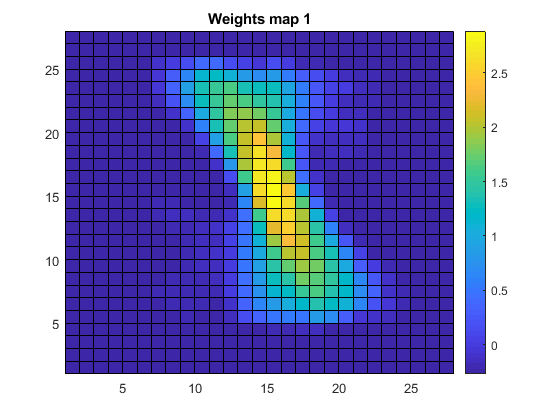

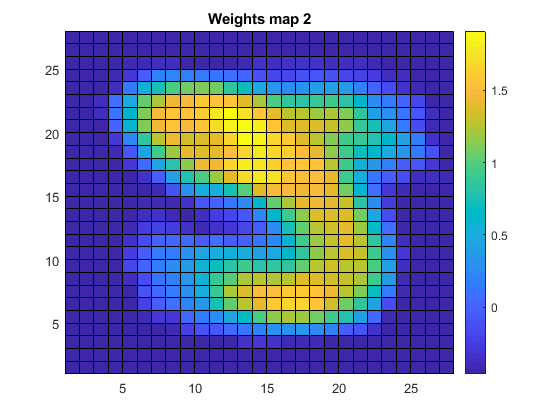

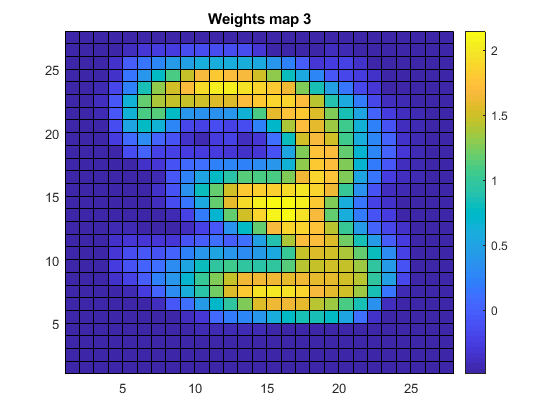

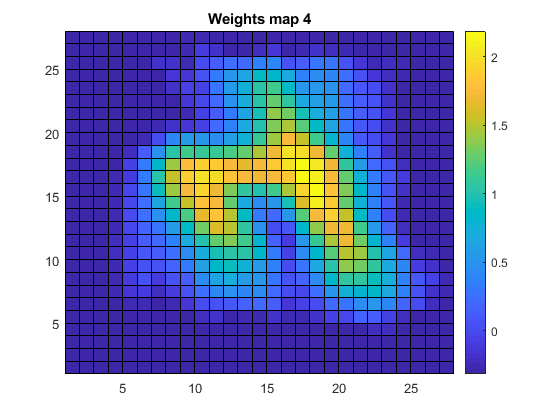

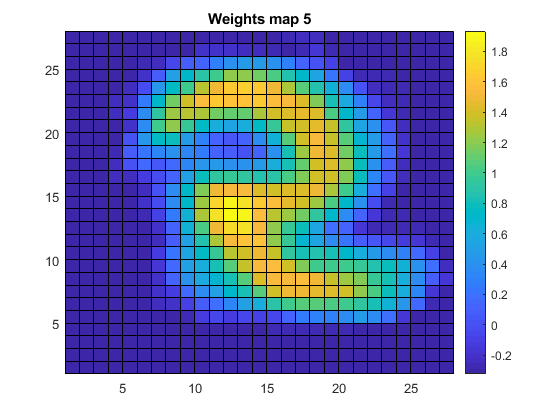

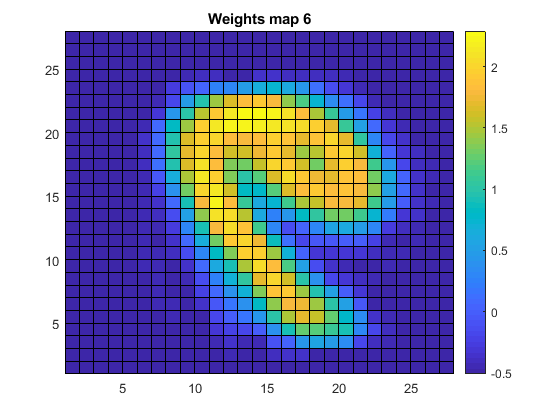

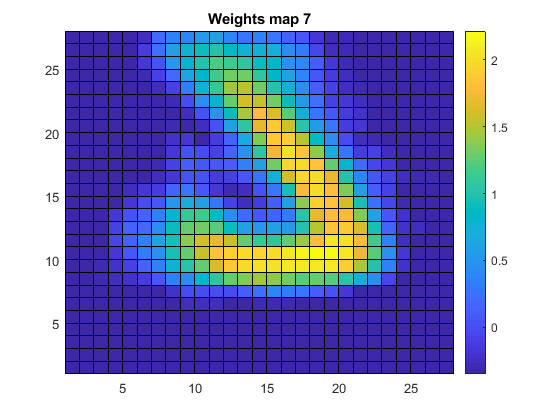

wMaps = zeros(28, 28, 10);
for i = 1:n
    wMaps(:, :, i) = reshape(w(:, i), [28,28]);
    figure()
    pcolor(wMaps(:, :, i))
    colorbar
    title(sprintf('Weights map %d', i-1))
end

## Classify the images

% Reset the arrays storing the spike trains
spkTrnsIn = zeros(nSyn, dpth, n);
% Reset the state of the neurons
v(1:n) = -70;
u(1:n) = -14;
% The highest firing rate
maxNu = 0;
% The index of the neuron with the highest firing rate
maxNuIndx = 0;
correctImg = 0;
times = 100;
for i = 1:size(testImgs, 3)
    % Reset the variables
    nuOut = zeros(n, 1);
    maxNu = 0;
    maxNuIndx = 0; 
    figure()
    hold on
    for t = 1:times
        img = testImgs(:, :, i);
        % After neurons have been stimulated wet le them relax
        % by sending a blank picture
        if (t > 0.7*times)
            img = zeros(28, 28);
        end
        parfor j = 1:10
            spksIn(:, j) = generateSpikes(img);
            spkTrnsIn(:, :, j) = updtSpkTrn(spksIn(:, j), spkTrnsIn(:, :, j));
            [spksOut(j), v(j), u(j)] = simulateNrn(spkTrnsIn(:, :, j), w(:, j), v(j), u(j), alpha);
            % Compute if neuron j is the one that has fired the most
            if (spksOut(j) == 1) 
                plot(t, j, strcat('k', '.'))
                nuOut(j) = nuOut(j) + spksOut(j);
            end           
        end
        [maxNu, maxNuIndx] = max(nuOut);
    end
    title(sprintf('Raster-graph for pic %d label %d', i, testLbls(i)));
    ylim([0, 11]);
    hold off
    % -1 is due to the labels starting from 0 instead of 1
    if (maxNuIndx-1 == testLbls(i))
        correctImg = correctImg + 1;
    end
    sprintf('Guessed label %d real label %d', maxNuIndx-1, testLbls(i))
end

ans = 'Guessed label 7 real label 7'

ans = 'Guessed label 2 real label 2'

ans = 'Guessed label 1 real label 1'

ans = 'Guessed label 0 real label 0'

ans = 'Guessed label 4 real label 4'

ans = 'Guessed label 1 real label 1'

ans = 'Guessed label 4 real label 4'

ans = 'Guessed label 6 real label 9'

ans = 'Guessed label 0 real label 5'

ans = 'Guessed label 7 real label 9'

ans = 'Guessed label 0 real label 0'

ans = 'Guessed label 6 real label 6'

ans = 'Guessed label 9 real label 9'

ans = 'Guessed label 0 real label 0'

ans = 'Guessed label 1 real label 1'

ans = 'Guessed label 0 real label 5'

ans = 'Guessed label 9 real label 9'

ans = 'Guessed label 7 real label 7'

ans = 'Guessed label 2 real label 3'

ans = 'Guessed label 9 real label 4'

ans = 'Guessed label 7 real label 9'

ans = 'Guessed label 6 real label 6'

ans = 'Guessed label 7 real label 6'

ans = 'Guessed label 8 real label 5'

ans = 'Guessed label 4 real label 4'

sprintf('Accuracy %f', correctImg/size(testImgs, 3))